%% Function definitions
fun_gaussian_sym = @(A,xy) A(1) * exp( - ( (xy{1}-A(4)).^2 + (xy{2}-A(5)).^2 ) / (2*A(3)^2) ) + A(2) + A(1) / A(6) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, ofset, sigma, x0, y0, s2n]

fun_gaussian = @(A,xy) A(1) * exp( - ( (xy{1}-A(5)).^2 / (2*A(3)^2) + (xy{2}-A(6)).^2 / (2*A(4)^2) )  ) + A(2) + A(1) / A(7) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, ofset, sx, sy, x0, y0, s2n]

getr = @(A,xy) sqrt( (xy{1}-A(4)).^2 + (xy{2}-A(5)).^2 );
getrr0 = @(A,xy) (1 - (getr(A,xy) / A(2) .* (getr(A,xy)<A(2))).^A(3)) .* (getr(A,xy)<A(2));
fun_box_z = @(A,xy) A(1) * getrr0(A,xy).^(3/2)  + A(1) / A(6) * randn(size(xy{1},1),size(xy{1},2));
    % A = [amplitude, r0, z, x0, y0, s2n]
    
%% Data setup
len_x = 300;
len_y = 300;
xy = {};
x = (1:1:len_x) ;
y = (1:1:len_y)';
[xy{1}, xy{2}] = meshgrid(x,y);

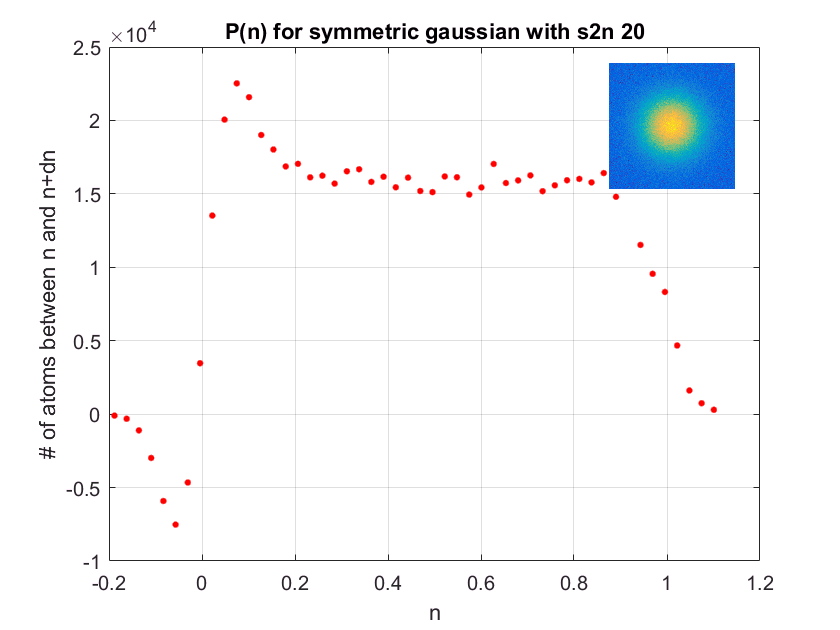

%% Symmetric Gaussian
A = [1, 0, 50, 150, 150, 20];
nxy = fun_gaussian_sym(A,xy);
[n_i, P_n] = extract_Pn(nxy,'bins',50,'plot_title',['P(n) for symmetric gaussian with s2n ', num2str(A(6))]);

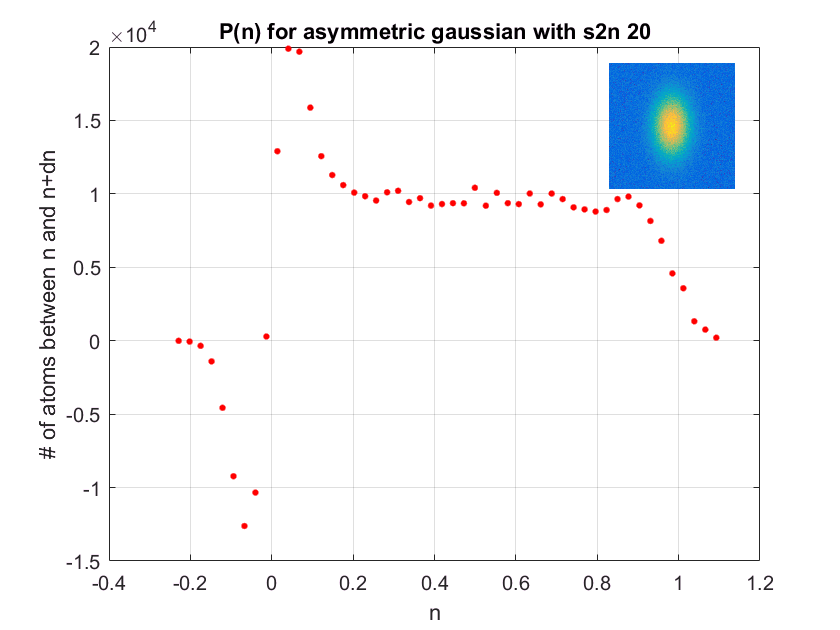

%% Asymmetric Gaussian
A = [1, 0, 30, 50, 150, 150, 20];
nxy = fun_gaussian(A,xy);
[n_i, P_n] = extract_Pn(nxy,'bins',50,'plot_title',['P(n) for asymmetric gaussian with s2n ', num2str(A(7))]);

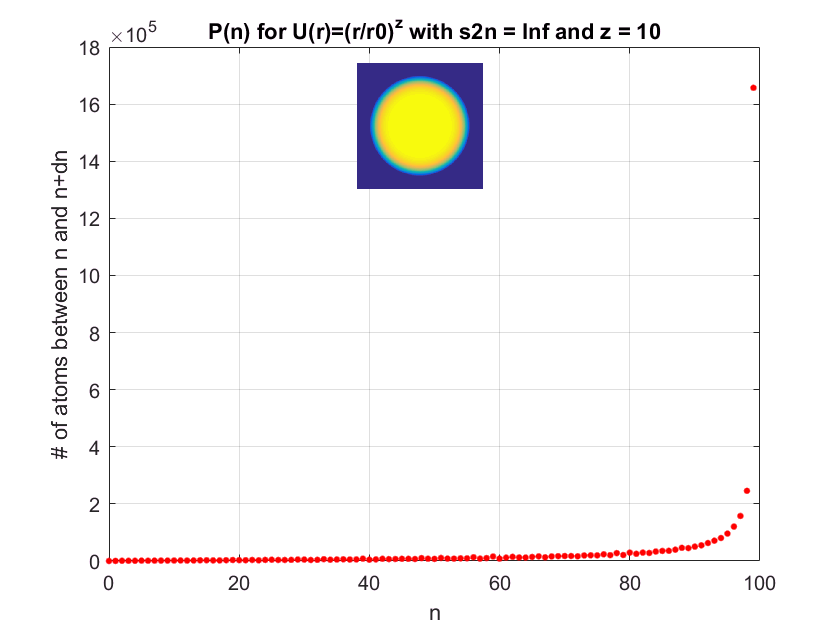

%% Box with (r/r0)^z
A = [100, 120, 10, 150, 150, inf];
nxy = fun_box_z(A,xy); 
% nxy = nxy + poissrnd(round(nxy));
[n_i, P_n] = extract_Pn(nxy,'bins',100,'plot_nxy_pos',[.4 .7 .2 .2],'plot_title',['P(n) for U(r)=(r/r0)^z with s2n = ', num2str(A(6)),' and z = ',num2str(A(3))]);

% %% Understanding poisson dist
% figure
% hist(poissrnd(100,1,1000))